f = @(x)((x^3+1)/x^2)

f = function_handle with value:
    @(x)((x^3+1)/x^2)


lagrangian_method(f,1,2,0.01,0.0001,10000)

ans = 1.2600

  f=@(x)0.01*sin(10*x)+(0.07*x.^2-0.4).^2

f = function_handle with value:
    @(x)0.01*sin(10*x)+(0.07*x.^2-0.4).^2


  x1 = lagrangian_method(f,-8,-0.5,0.05,0.001,10000)

x1 = -2.0978

f=@(x)0.01*sin(10*x)+(0.07*x.^2-0.4).^2

f = function_handle with value:
    @(x)0.01*sin(10*x)+(0.07*x.^2-0.4).^2


  x2 = lagrangian_method(f,1,8,0.05,0.001,10000)

x2 = 2.3653

px = [-10 -5 0 5 10];
py = [0.0001 -0.1 0 0.1 -0.0001];
stopien=5

stopien = 5

W = polyfit(px, py, stopien)

W =    -0.0000    0.0000    0.0011   -0.0000         0    0.0000


fx=@(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x

fx = function_handle with value:
    @(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x


y1 = lagrangian_method(fx,-0.2750 , 0.0063,0.05,0.001,10000)

y1 = -0.1004

y2 = lagrangian_method(fx,-5.4371 , -2.2335,0.05,0.001,10000)

y2 = -3.8524

y3 = lagrangian_method(fx,20.9746 , 37.1929,0.05,0.001,10000)

y3 = 26.7602

y4 = lagrangian_method(fx,-0.7086 , 0.2406,0.05,0.001,10000)

y4 = -0.1003

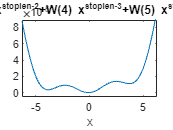

ezplot(fx)